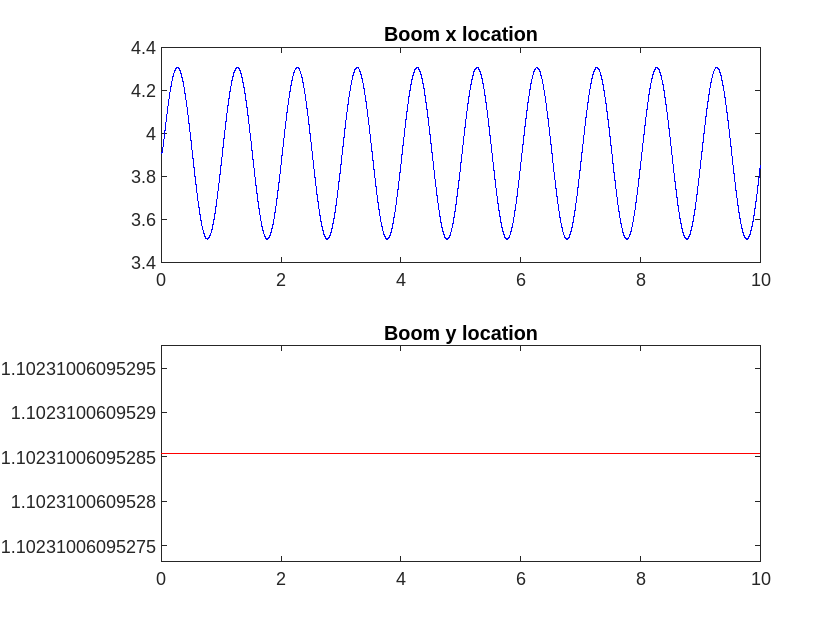

% Assuming your data is in a variable called 'val'
% 'val' is a 3D array with dimensions (M x N x P)

% Specify the color for the plot
line_color = [60 100 175] / 25;

% Define the time vector (assuming 'time' is available)
time = out.boom_x.time;
x_boom = out.boom_x.signals.values;
x_boom = squeeze(x_boom);

y_boom = out.boom_y.signals.values;
y_boom = squeeze(y_boom);

% Iterate through each slice along the third dimension and plot it

subplot(2,1,1)
plot(time, x_boom, 'color', 'blue')
title("Boom x location")
subplot(2,1,2)
plot(time,y_boom, 'color', 'red')
title("Boom y location")% Create a figure

%Save data into csv file 
time

time =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001


x_boom

x_boom =     3.9072
    3.9072
    3.9072
    3.9072
    3.9072
    3.9072
    3.9072
    3.9072
    3.9072
    3.9072


y_boom

y_boom =     1.1023
    1.1023
    1.1023
    1.1023
    1.1023
    1.1023
    1.1023
    1.1023
    1.1023
    1.1023


all = [time, x_boom, y_boom]

all =          0    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0000    3.9072    1.1023
    0.0001    3.9072    1.1023


T = array2table(all);
T.Properties.VariableNames(1:3) = {'time', 'x_boom', 'y_boom'}

T = 10058×3 table
       time       x_boom    y_boom
    __________    ______    ______

             0    3.9072    1.1023
     2.543e-06    3.9072    1.1023
    5.0859e-06    3.9072    1.1023
    7.6289e-06    3.9072    1.1023
    1.0172e-05    3.9072    1.1023
    1.5066e-05    3.9072    1.1023
    2.2513e-05    3.9072    1.1023
    3.2929e-05    3.9072    1.1023
    4.9587e-05    3.9072    1.1023
    8.2823e-05    3.9072    1.1023
    0.00013249    3.9072    1.1023
    0.00018215    3.9072    1.1023
    0.00023182    3.9072    1.1023
    0.00028148    3.9072    1.1023
    0.00033115    3.9072    1.1023
    0.00038081    3.9072    1.1023


writetable(T, 'training1.csv')
%writematrix(all, "training_1.csv")